% 广度优先搜索 Breadth First Search，其中一个应用就是反映遍历一张图的过程和结果

% 一块农田可以由 9 块下面的基本形式的单元拼接而成，可以在每个单元的中心挖井以灌溉农田，
% 现在需要确定，由下面基本单元任意组合的某块农田（先尝试由 9 个基本单元组成正方形的情况）最少需要多少口井才能保证所有单元都灌溉到。
% 比如下面形式的农田是由 
%   ADC
%   FJK
%   IHE
% 九种基本单元依次拼接而成的，可以确定，最少只需要 3 口井就能灌溉所有的单元。


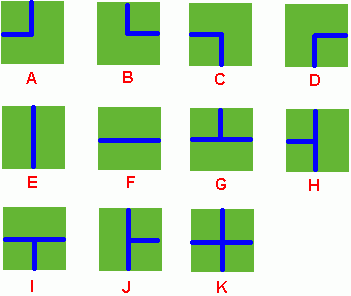    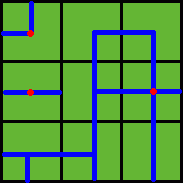

% 该问题的实质是遍历问题，
% 把每个基本单元的中心看作一个 Vertex，然后取其中一个 Vertex 作为 Source Vertex，由此出发看其能够遍历其他 Vertex 中的哪些
% 剩下的 Vertex 又取其中一个作为第二个 Source Vertex，接着遍历，
% 直到最后只剩下一个 Vertex 为止，这个是最后一个 Source Vertex 
% 这样需要的井数就是 Source Vertex 数

% 主程序段，输入 A ~ L 的任意组合，求得需要多少口井才能浇灌所有的单元

unitMatrixLabel = ['L', 'D', 'C', 'D'; 'F', 'J', 'C', 'K'; 'I', 'H', 'D', 'L'; 'K', 'A', 'B', 'E']

unitMatrixLabel = 4×4 char 数组
    'LDCD'
    'FJCK'
    'IHDL'
    'KABE'


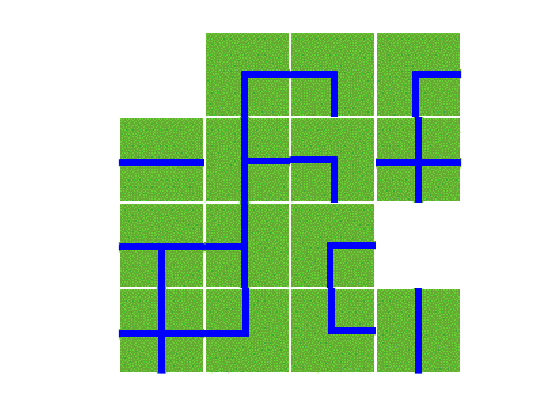


drawUnitMergeImg(unitMatrixLabel);   % 将随意单元组合拼接成的农田显示成图片

Note: the xy coordinates of a vertex is different from the element(row,col) order of a matrix!
Here elements are displayed in (row,col) format.


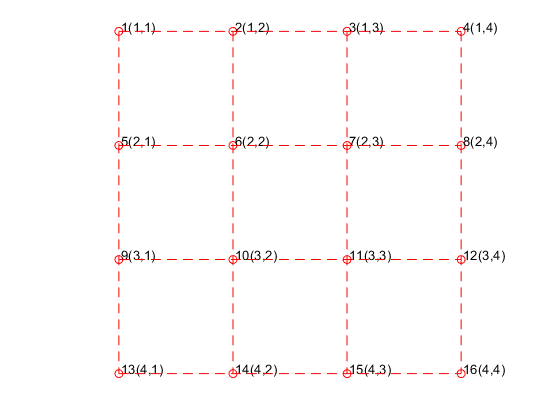

drawGraph(unitMatrixLabel);   % 将拼合图片的节点和连线的一般结构用图 Graph 的形式画出来，以方便分析用什么样的数据结构来表示这个图


wellNums = calWellNums(unitMatrixLabel)

wellNums = 5

function drawUnitMergeImg(unitMatrixLabel)    % 将随意单元组合拼接成的农田显示成图片
    
    [rowNum, colNum] = size(unitMatrixLabel);    % 拼合图片的横、竖单元数
        
    unitImSize = [63,63];   % 每个单元小图片的像素大小
    
    imMerge = zeros(rowNum*unitImSize(1), colNum*unitImSize(2), 3);   % 预先建立对应大小的空白画布
    
    xStart = 1;    % 第一个单元（左上角）的起始坐标
    yStart = 1;
    
    for i = 1:rowNum
        for j = 1:colNum
            fileName = ['C:\Users\JIMMY\Documents\MATLAB\RealScript\015BreathFirstSearch\', unitMatrixLabel(i,j), '.gif'];
            [unitImage, map] = imread(fileName);   % gif 文件读取的时候不像 RGB (jpg) 格式，其颜色信息另外储存于一个矩阵中
            if ~isempty(map)
                unitImage = ind2rgb(unitImage,map);    % 将颜色信息矩阵和图像矩阵合并成一个 x*y*3 矩阵
            end        
            imMerge(xStart:i*unitImSize(1), yStart:j*unitImSize(2), :) = unitImage;    % 依次拼接各个单元
            yStart = yStart + unitImSize(2);        
        end
        xStart = xStart + unitImSize(1);
        yStart = 1;    % 另起一行，回到开头
    end
    
    image(imMerge);
    axis equal;
    axis off;
end


function drawGraph(unitMatrixLabel)    % 将拼合图片的节点和连线的一般结构用图 Graph 的形式画出来，以方便分析用什么样的数据结构来表示这个图
    [rowNum, colNum] = size(unitMatrixLabel);    % 拼合图片的横、竖单元数   
    
    % 注意在图中显示的时候，点坐标是 x 在前，y 在后，而对于矩阵的元素而言，其标记是行索引在前，列索引在后，因此是相反的。
    disp('Note: the xy coordinates of a vertex is different from the element(row,col) order of a matrix!');
    disp('Here elements are displayed in (row,col) format.');
    ii=1:rowNum;
    jj=1:colNum;
    [x,y]=meshgrid(jj,ii);   % 绘图坐标要和矩阵索引反过来写，因此 j 对应 x 坐标，i 对应 y 坐标
    figure
    scatter(x(:),-y(:),'ro')
    hold on;
    
    order = 1;
    for i = 1:rowNum
        for j = 1:colNum
            text(j+0.02, -i+0.05, [num2str(order), '(' num2str(i) ',' num2str(j) ')']);   % 绘图坐标要和矩阵索引反过来写，因此 j 对应 x 坐标
            
            plot([j,j], [-ii(1), -ii(end)], 'r--');   % 坐标 (1,-1)--(1,-3)，画横线
            plot([jj(1), jj(end)], [-i,-i], 'r--');   % 画竖线
            
            order = order + 1;
        end
    end
    
    axis equal;
    axis off;
end


function unitMatrix = unitCodingSys(unitMatrixLabel)    % 将字符构成的关于各单元组合成的整体的列表转换成由自创编码组合成的二维元胞数组
    % 首先考虑如何以数学符号的方式来表示各个单元能否和相邻的其他单元相连接，
    % 对于 A，只有左边和上边的方向可以和相邻单元的顶点构成 Edge，
    % 因此首先要求另一个点位于其左边或者上边，同时位于右边的时候可以和右边的顶点沟通构成 Edge
    % 如果 A 表示成 A = [1, 1, 0, 0]，从左边开始编号，左 - 上 - 右 - 下
    % 只有 X = [x, x, 1, x] 位于 A 右边的时候可以构成 Edge，或者 X = [x, x, x, 1] 位于 A 上边的时候可以构成 Edge
    % 因此各单元的表示如下
    % A = [1, 1, 0, 0]
    % B = [0, 1, 1, 0]
    % C = [1, 0, 0, 1]
    % D = [0, 0, 1, 1]
    % E = [0, 1, 0, 1]
    % F = [1, 0, 1, 0]
    % G = [1, 1, 1, 0]
    % H = [1, 1, 0, 1]
    % I = [1, 0, 1, 1]
    % J = [0, 1, 1, 1]
    % K = [1, 1, 1, 1]
    % 当拼接成 AD 时，A(3) = 0, D(1) = 0，A(3) + D(1) = 0，因此两者不相通
    % 当拼接成 A
    %         F 时，A(4) = 0, F(2) = 0，A(4) + F(2) = 0，因此两者也不相通
    % 由此可以构建起基本的运算规则来判断两个 Vertices 间是否相通
    % 当连线之和为 2 时相通，0 或 1 为不相通
    % 
    % 如果想构造不规则的农田，那么可以把缺失的部分用空单元暂时填补，
    % 这个空单元可以表示为 L = [0, 0, 0, 0]，然后求得需要的井数之后，减去空单元数即为不规则农田实际需要的井数

    unitCoding = {[1, 1, 0, 0], [0, 1, 1, 0], [1, 0, 0, 1], [0, 0, 1, 1], ...    % 对应 A, B, C, D, E, F, G, H, I, J, K, L。其中 L 为 [0, 0, 0, 0]
                [0, 1, 0, 1], [1, 0, 1, 0], [1, 1, 1, 0], [1, 1, 0, 1], ...
                [1, 0, 1, 1], [0, 1, 1, 1], [1, 1, 1, 1], [0, 0, 0, 0]};

    unitMatrix = unitCoding(unitMatrixLabel(:,:)-64);   % A 的 ASCII 码为 64，(:,:) 可以复制为二维元胞数组
    
    % 该元胞数组反映每个节点的单元构成，不宜用数组的方式表示否则会变成下面的形式    
    % unitMatrix = 3×12    
    %     1     1     0     0     0     0     1     1     1     0     0     1
    %     1     0     1     0     0     1     1     1     1     1     1     1
    %     1     0     1     1     1     1     0     1     0     1     0     1
end


function adjList = graph2AdjList(unitMatrixLabel)
    % 需要构建一个描述整个拼图各单元相邻关系的普遍结构（暂不考虑各单元差异），并以恰当的数据结构来表示
    % 表示图的数据结构主要有三种，Edge List，Adjacency Matrix，Adjacency List，都不能反映节点的空间关系
    % 如果采用 vertexMatrix = [1, 2, 3, 4, 5, 6, 7, 8, 9] 一维数组来表示 9 个单元构成的整个农田，
    % 然后构建 Adjacency Matrix，只考虑相邻关系的节点与节点间是否连接，可以描述如下
    %
    %     1   2   3   4   5   6   7   8   9   
    % 
    % 1   0   1   0   1   0   0   0   0   0           
    % 2   1   0   1   0   1   0   0   0   0
    % 3   0   1   0   0   0   1   0   0   0
    % 4   1   0   0   0   1   0   1   0   0
    % 5   0   1   0   1   0   1   0   1   0
    % 6   0   0   1   0   1   0   0   0   1
    % 7   0   0   0   1   0   0   0   1   0
    % 8   0   0   0   0   1   0   1   0   1
    % 9   0   0   0   0   0   1   0   1   0
    %
    % 依据上面的 Adjacency Matrix，可以确定各单位/节点是否可以有连接，但并不能表示连接的空间方位关系
    % 因此上面的结构并不是十分直观方便。
    % Edge List 和 Adjacency List 也存在同样的缺点
    
    % 在节点少的时候，可以采用手工构建上述的数据结构
    % 但在节点多的时候，则需要研究其空间方位关系及由此带来的限制条件
    % 以便能够用程序自动生成上述数据结构
    
    % 由此需要考虑采用二维的结构，来记录节点序号及相应坐标
    % 比如 vertexOrderMatrix = [1, 2, 3; 4, 5, 6; 7, 8, 9]，
    % 但同时又按照通常的邻接链表建立关于各节点间连线的记录
    
    unitMatrix = unitCodingSys(unitMatrixLabel);   % 返回的是二维元胞数组，含有各单元的编码列表
    [rowNum, colNum] = size(unitMatrixLabel);    % 拼合图片的横、竖单元数
    len1D = rowNum*colNum;    % 拼合图片整体转换为一维矩阵时的长度（单元总个数）
    
    % 将节点编号并对应空间坐标，转换成数学描述如下

    vertexOrderMatrix = zeros(rowNum,colNum);    % 该矩阵将让二维的节点坐标对应一个一维的序号编码
    
    
    vertexMatrix = zeros(3, len1D);    % 构建一个反 vertexOrder 表，由节点序号（第一行）可以知道其在二维空间的坐标（储存于第二行和第三行），这样便于提取坐标
    
    
    unitMatrix1D = cell(1,len1D);   % 将 unitMatrix 二维元胞数组也同时转变为一维元胞数组，不过，即使不作这样的转换，unitMatrix(4) 也等于 unitMatrix(2,1)
    
    order = 1;        
    for i = 1:rowNum
        for j = 1:colNum        
            vertexOrderMatrix(i,j) = order;   % 赋予序号
            
            vertexMatrix(1,order) = order;   % 序号
            vertexMatrix(2,order) = i;   % 行坐标
            vertexMatrix(3,order) = j;   % 列坐标
            
            unitMatrix1D{order} = unitMatrix{i,j};
            
            order = order + 1;
        end
    end    
    
    % 上面的结构只是记录了节点的情况，还需要构建邻接列表来描述各节点间连线的情况，
    % 如果没有各单元的条件限制的话，应当是相邻的上下左右节点可以相连
    
    % 由于每个节点赋予不同的单元的时候，其与邻近节点的能否连接会相应变化，
    % 因此在一般情况的连接（相邻的上下左右节点可以相连）的基础上需要进一步依据各单元的具体情况判断是否可以相连
    % 只有符合各单元限制条件的连线才添加到邻接列表中
    
    % 对于 vertexOrderMatrix = [1, 2, 3; 4, 5, 6; 7, 8, 9]
    % 如果一开始从 (1,1) 出发，只需要检测  (1,1).(3)、 (1,1).(4) 方向上的连接情况
    % 不同位置上的单元需要作连接情况检测的情况各不相同，可以列表如下
    %
    % 第一行横连线   [(1,1).(3), (1,2).(1)] , [(1,2).(3), (1,3).(1)]
    % 
    % 第一二行纵连线 [(1,1).(4), (2,1).(2)] , [(1,2).(4), (2,2).(2)] , [(1,3).(4), (2,3).(2)]
    %
    % 第二行横连线   [(2,1).(3), (2,2).(1)] , [(2,2).(3), (2,3).(1)]
    %
    % 第二三行纵连线 [(2,1).(4), (3,1).(2)] , [(2,2).(4), (3,2).(2)] , [(2,3).(4), (3,3).(2)]
    %
    % 第三行横连线   [(3,1).(3), (3,2).(1)] , [(3,2).(3), (3,3).(1)]
    %
    % 总共需要判断 10 条连线，将 A、B 等的编码代入即可判断在各单元有条件限制的情况是否能相连
    % 比如，对于 (1,1) 为 X 单元时，要判断其与 (2,2) 为 Y 单元的连接情况，
    % 需要计算 X(3)+Y(1) 的结果，如果等于2，就是连接，否则是断开，可以在上面构造 adjList 的基础上紧接着判断
    %
    % 上面是一条条连线列表而成，要应对拼接单元数量变化的情况，可以进一步构建判断实际连线情况的自动算法
    
    adjListR = {};    % 建立储存实际连接情况的邻接列表
    
    for k = 1:len1D    % 
        if (vertexMatrix(2,k)==1)&(vertexMatrix(3,k)==1)   % 第一行第一列（起点，序号 1 节点），vertexMatrix(2,k) 的 2 代表行坐标，3 代表列坐标
            adjListR{k} = [];
            if unitMatrix1D{k}(3) + unitMatrix1D{k+1}(1) == 2    % 需要依据位于该坐标的实际的单元来判断相邻节点（右和下）是否能够连线
                adjListR{k} = [adjListR{k}, k+1];            
            end
            if unitMatrix1D{k}(4) + unitMatrix1D{k+colNum}(2) == 2
                adjListR{k} = [adjListR{k}, k+colNum];
            end        
            % 以上是判断第一行第一列与第一行第二列的节点以及第二行第一列的节点是否能构成连线
            
        elseif (vertexMatrix(2,k)==1)&(vertexMatrix(3,k)>1)&(vertexMatrix(3,k)<colNum)    % 第一行，但不是该行起点和行终点，有左右下三个邻接点
            adjListR{k} = [];
            if unitMatrix1D{k}(1) + unitMatrix1D{k-1}(3) == 2    % 左邻接点
                adjListR{k} = [adjListR{k}, k-1];
            end
            if unitMatrix1D{k}(3) + unitMatrix1D{k+1}(1) == 2
                adjListR{k} = [adjListR{k}, k+1];            
            end
            if unitMatrix1D{k}(4) + unitMatrix1D{k+colNum}(2) == 2
                adjListR{k} = [adjListR{k}, k+colNum];
            end        
            % 以上是判断该节点和第一行前后节点及第二行同一列节点是否实际构成连线
                    
        elseif (vertexMatrix(2,k)==1)&(vertexMatrix(3,k)==colNum)    % 第一行终点，有左下两个邻接点
            adjListR{k} = [];
            if unitMatrix1D{k}(1) + unitMatrix1D{k-1}(3) == 2
                adjListR{k} = [adjListR{k}, k-1];            
            end
            if unitMatrix1D{k}(4) + unitMatrix1D{k+colNum}(2) == 2
                adjListR{k} = [adjListR{k}, k+colNum];
            end
            
        elseif (vertexMatrix(2,k)>1)&(vertexMatrix(2,k)<rowNum)&(vertexMatrix(3,k)==1)   % 非第一行和最后一行的第一列
            adjListR{k} = [];
            if unitMatrix1D{k}(2) + unitMatrix1D{k-colNum}(4) == 2
                adjListR{k} = [adjListR{k}, k-colNum];
            end
            if unitMatrix1D{k}(3) + unitMatrix1D{k+1}(1) == 2
                adjListR{k} = [adjListR{k}, k+1];            
            end
            if unitMatrix1D{k}(4) + unitMatrix1D{k+colNum}(2) == 2
                adjListR{k} = [adjListR{k}, k+colNum];
            end
                    
        elseif (vertexMatrix(2,k)>1)&(vertexMatrix(2,k)<rowNum)&(vertexMatrix(3,k)>1)&(vertexMatrix(3,k)<colNum) % 非第一和最后一行的非第一和最后一列
            adjListR{k} = [];
            if unitMatrix1D{k}(2) + unitMatrix1D{k-colNum}(4) == 2
                adjListR{k} = [adjListR{k}, k-colNum];
            end
            if unitMatrix1D{k}(1) + unitMatrix1D{k-1}(3) == 2
                adjListR{k} = [adjListR{k}, k-1];            
            end
            if unitMatrix1D{k}(3) + unitMatrix1D{k+1}(1) == 2
                adjListR{k} = [adjListR{k}, k+1];            
            end
            if unitMatrix1D{k}(4) + unitMatrix1D{k+colNum}(2) == 2
                adjListR{k} = [adjListR{k}, k+colNum];
            end
                    
        elseif (vertexMatrix(2,k)>1)&(vertexMatrix(2,k)<rowNum)&(vertexMatrix(3,k)==colNum)    % 非第一和最后一行的最后一列
            adjListR{k} = [];
            if unitMatrix1D{k}(2) + unitMatrix1D{k-colNum}(4) == 2
                adjListR{k} = [adjListR{k}, k-colNum];
            end
            if unitMatrix1D{k}(1) + unitMatrix1D{k-1}(3) == 2
                adjListR{k} = [adjListR{k}, k-1];            
            end
            if unitMatrix1D{k}(4) + unitMatrix1D{k+colNum}(2) == 2
                adjListR{k} = [adjListR{k}, k+colNum];
            end
                    
        elseif (vertexMatrix(2,k)==rowNum)&(vertexMatrix(3,k)==1)    % 最后一行的第一列
            adjListR{k} = [];
            if unitMatrix1D{k}(2) + unitMatrix1D{k-colNum}(4) == 2
                adjListR{k} = [adjListR{k}, k-colNum];
            end       
            if unitMatrix1D{k}(3) + unitMatrix1D{k+1}(1) == 2
                adjListR{k} = [adjListR{k}, k+1];            
            end
            
        elseif (vertexMatrix(2,k)==rowNum)&(vertexMatrix(3,k)>1)&(vertexMatrix(3,k)<colNum)    % 最后一行的非第一和最后一列    
            adjListR{k} = [];
            if unitMatrix1D{k}(2) + unitMatrix1D{k-colNum}(4) == 2
                adjListR{k} = [adjListR{k}, k-colNum];
            end
            if unitMatrix1D{k}(1) + unitMatrix1D{k-1}(3) == 2
                adjListR{k} = [adjListR{k}, k-1];            
            end
            if unitMatrix1D{k}(3) + unitMatrix1D{k+1}(1) == 2
                adjListR{k} = [adjListR{k}, k+1];            
            end
            
        elseif (vertexMatrix(2,k)==rowNum)&(vertexMatrix(3,k)==colNum)    % 最后一行的最后一列（终点）
            adjListR{k} = [];
            if unitMatrix1D{k}(2) + unitMatrix1D{k-colNum}(4) == 2
                adjListR{k} = [adjListR{k}, k-colNum];
            end
            if unitMatrix1D{k}(1) + unitMatrix1D{k-1}(3) == 2
                adjListR{k} = [adjListR{k}, k-1];            
            end
            
        end
        adjListR{k};
    end
    adjList = adjListR;
end


function wellNums = calWellNums(unitMatrixLabel)    % 通过遍历的方法算出要遍历几次才能遍历完所有节点，遍历的次数就是需要统计的井数
    [rowNum, colNum] = size(unitMatrixLabel);    % 拼合图片的横、竖单元数
    len1D = rowNum*colNum;    % 拼合图片整体转换为一维矩阵时的长度（单元总个数）
    adjList = graph2AdjList(unitMatrixLabel);    % 描述整个拼图各单元/按顺序编号的节点间是否形成连线的邻接列表

    % 获得所有连线的通断情况（邻接列表）之后，可以开始进行遍历，其中的“孤岛”单元也需要遍历一次
    %
    % 关于宽度优先搜索的遍历步骤如下
    %
    % 假定是对一个 3 x 3 矩阵并且相邻节点都相连的情况进行遍历
    % 首先从 (1,1) 开始出发，然后先到 (1,2)，后到 (2,1)，这样就遍历完距离 (1,1) 为 1 的第一层节点
    % 再从 (1,2) 出发，到 (1,3) 和 (2,2)，这样从 (2,1) 出发就不能到 (2,2) ，只能到(3,1)，这样就遍历完距离 (1,1) 为 2 的第二层节点
    % 再从 (1,3) 出发，到 (2,3)，这样从 (2,2) 出发就不能到 (2,3) ，只能到(3,2)，这样就遍历完距离 (1,1) 为 3 的第三层节点
    % 最后从 (2,3) 出发，到 (3,3)，这样就遍历完距离 (1,1) 为 3 的第四层节点
    %
    % 对于一个二维矩阵，确定某一个点 (x,y) 到 (1,1) 的距离，距离为 d = (x-1) + (y-1)，这样就可以确定每次先遍历同一距离的所有节点再往下遍历
    %
    % 由于之前已经将二维矩阵改造为一维，并且通过邻近列表可以确定某个节点的下一层节点，因此依据邻近列表即可实现一层层的遍历
    %
    % 具体步骤如下
    %
    % 从序号 1 节点出发，如果节点 1 和其他节点有连接，则通过邻接列表 adjList(1) 对应的列表中的数字，
    % 可以知道离其距离为 1 的节点有有哪些，这些节点就是序号 1 节点的第一层遍历的节点
    % 接着从第一层被遍历的节点中取一个节点，遍历这个节点所连接的节点（除去其来源节点/父节点）
    % 再从第一层被遍历的节点中取第二个节点，也遍历这个节点所连接的节点（除去其来源节点/父节点，以及和前一个节点共有的子节点）
    % 如此循环遍历完第一次被遍历的节点的各自下一层子节点，同时要避免两次遍历共同的子节点
    % 再接着遍历第三层子节点，直至到所能达到的最深层的所有子节点
    % 
    % 如果序号 1 节点和其他节点没有连接，在记数一次遍历操作之外还需要以下一个序号节点为起点进行遍历
    % 
    % 一次遍历操作完成之后，需要检查所有节点是否已经遍历完，
    % 如果还有节点还没有被遍历到，则从这些节点中选择一个节点作为起点，继续遍历操作，直至遍历完所有节点。
    %
    % 上述操作，需要记录遍历到哪个节点及其子节点，这个遍历顺序记录可以用 Queue 数据结构结合邻接列表实现
    % 还需要一个列表记录整个节点有哪些已经被遍历过，以便一方面排除已经被遍历过的共享子节点，另一方面用于记录当次遍历操作完之后还剩哪些节点
    % 还需要一个变量记录从起点出发的遍历操作次数
        
    % Queue 可以记录是否已经从某个点出发，向下一层遍历了。    
    % 比如在完成从 (1,2) 出发，到 (1,3) 和 (2,2) 的访问后，需要判断 (2,1) 是否已经执行了向下一层遍历的操作，
    % 对一个 3 x 3 矩阵并且相邻节点都相连的情况，Queue 的具体操作步骤如下
    % 先将 (1,1) enqueue 到队列，当它向下一层访问的时候就 dequeue，(1,2) 和 (2,1) 分别 enqueue，(1,2) - (2,1)
    % (1,2) dequeue，然后 (1,3) 和 (2,2) enqueue，(2,1) 仍然在 queue 中，(2,1) - (1,3) - (2,2)
    % (2,1) dequeue，(3,1) enqueue，(1,3) 和 (2,2) 仍然在 queue 中，(2,2) 是共享子节点，不再重复 enqueue，(1,3) - (2,2) - (3,1)
    % (1,3) dequeue，(2,3) enqueue，(2,2) - (3,1) - (2,3)
    % (2,2) dequeue，(3,2) enqueue, (3,1) - (2,3) - (3,2)
    % (3,1) dequeue，没有 enqueue，(2,3) - (3,2)
    % (2,3) dequeue，(3,3) enqueue，(3,2) - (3,3)
    % (3,2) 和 (3,3) 依次 dequeue，没有 enqueue
    % 经过上面的操作就完成了整个遍历，并且保证没有重复遍历。
    
   
    
    nullUnitNum = 0;
    
    for m = 1:rowNum    % 计算 L [0, 0, 0, 0] 空白单元的个数
        for n = 1:colNum
            if unitMatrixLabel(m,n) == 'L'
                nullUnitNum = nullUnitNum + 1;
            end
        end
    end

    wellNums = 0 - nullUnitNum;   % 需要的井数，也就是需要的遍历轮数，但需要减去 L [0, 0, 0, 0] 空白单元的个数
    
    leftUnit = ones(1,len1D);    % 用于记录哪些节点被遍历过了，初始都设为 1，遍历过的节点则将值改为 0    
    
    while(sum(leftUnit(:))>0)    % 在所有的节点中如果还有节点还没有被遍历，就需要开始一轮新的遍历，这里把孤立节点也放进来        

        j = 1;    
        while(leftUnit(j)==0)    % 从 leftUnit 中找出排在最前面的还没有被遍历的节点的序号，作为本次遍历操作的起点，第一次应该是 1
            j = j + 1;
        end
        currentQueue = j;    % 将起点 enqueue 到 Queue 中
        leftUnit(j) = 0;    % enqueue 后要将起点的遍历状态修改为 0
        
        while(not(isempty(currentQueue)))    % Queue 如果不为空，则这一次遍历还没有结束，继续 enqueue和/或 dequeue 操作
            enqueueItemsBeforeCheck = adjList{currentQueue(1)};    % 取即将 dequeue 的单元直接相连接的节点列表，
                                                                   % 但该列表包括了其父节点和可能已经被遍历过的共享子节点，需要排除这两者
            enqueueItems = [];    % 用于储存排除了父节点和已经被遍历过的共享子节点后的连接节点，用于 enqueue 操作
            if not(isempty(enqueueItemsBeforeCheck))    % 如果某个起点节点为孤岛，则其连接列表为空，不为空的话，则检测有无上面说的需要排除的节点
                lenEnqueueItems = length(enqueueItemsBeforeCheck);
                for i = 1:lenEnqueueItems
                    if leftUnit(enqueueItemsBeforeCheck(i)) ~= 0    % 如果待 enqueue 的单元已经被遍历过，就要从待 enqueue 的列表中去除
                        enqueueItems = [enqueueItems, enqueueItemsBeforeCheck(i)];   % 构建经过排除后的需要 enqueue 的节点列表
                    end
                end
            end
            leftUnit(enqueueItems(:)) = 0;   % 把准备 enqueue 的节点都从 leftUnit 中去除，但 dequeue 无需再从 leftUnit 去除，因为在 enqueue 时就已去除  
            currentQueue = queuing(currentQueue, enqueueItems);   % 每次只 dequeue 一个节点，即 currentQueue(1)，因此无需构建 dequeueItem
        end
        % 经过上面的循环 Queue 操作，某个起点和与它相连接的所有节点就都遍历过了，
        
        wellNums = wellNums + 1;    % 完成一轮遍历，记录遍历轮数，也是需要的井数
        
        % 需要寻找下一个还没有被遍历过的节点，并以此为起点，开始新一轮遍历        
    end
end


function currentQueue = queuing(queue, enqueueItems)    % 进行 queue 操作
    queue = queue(2:end);    % 先 dequeue 掉位于头部的节点
    currentQueue = [queue, enqueueItems];    % 再在 Queue 尾部 enqueue 相应节点
end